## Case study: IEEE 118 bus system

clc;
clear all;

N=118;
T=24; % can be changed

** read the brance data of 118-bus file**

case_filename = '.\data\ieee118cdf_2.txt';
line_info = importdata(case_filename);
cols=[1 2 8];
linedata=line_info.data(:,cols);
M=size(linedata,1);
H= GSDF(linedata);
linecapacity_filename='.\data\additional-files\Lines.csv';
fmax= xlsread(linecapacity_filename, 1, 'D2:D187');

**generator data and load data (no wind)**

P_filename='.\data\IEEE118bus_data_figure.xls';
generator_info=xlsread(P_filename,1,'E2:M55');
[~,generator_type,~]=xlsread(P_filename,1,'S2:S55');
load_info=xlsread(P_filename,4,'D2:F92');
g_min=zeros(N,1);
g_max=zeros(N,1);
d_basic=zeros(1,N);
g_type=cell(N,1);
fill_no=cell(1,1);
fill_no(1,1)={'no'};
% ramping constraints
DR=zeros(N,1);
UR=zeros(N,1);

for i=1:N
    if ismember(i,generator_info(:,1))
        bus=find(generator_info(:,1)==i);
        g_min(i,1)=generator_info(bus,2);
        g_max(i,1)=generator_info(bus,3);
        DR(i,1)=generator_info(bus,9);
        UR(i,1)=generator_info(bus,8);
        g_type(i,1)=generator_type(bus,1);
    else
        g_type(i,1)=fill_no;
    end
    if ismember(i,load_info(:,1))
        bus=find(load_info(:,1)==i);
        d_basic(1,i)=load_info(bus,3);  % can be changed
    end
end

% ramp_ratio=0.7;
% DR=ramp_ratio*g_max;
% UR=ramp_ratio*g_max;

**price (there is no need to change the optimization function)**

carbon_tax=0.2; % can be changed
[p,q]=gen_unit_price(g_type,carbon_tax); % with parameter inside, can be changed

**demand generation**

reserve=500;
% Amp_max=(sum(g_max)-reserve)/sum(d_basic);
% Amp_min=(sum(g_min)+reserve)/sum(d_basic);
Amp_max=1.6;
Amp_min=0.8;
perturbation=Amp_max-Amp_min; % can be changed
medium_value=(Amp_max+Amp_min)/2;
% rand_multiplier=(perturbation*rand(T,N)-0.5)*2;
% d_r=d_basic.*(1+rand_multiplier);
rand_multiplier=perturbation*(rand(T,1)-0.5)+medium_value;
d_r=rand_multiplier*d_basic;

**wind and uncertain variables**

w_loc=[18,24,27,31,100,82,92,54,69,104,112];
w_num=size(w_loc,2);
w_basic=zeros(1,N);
for i=1:w_num
    loc=w_loc(i);
    w_basic(1,loc)=20; 
end
w_perturbation=0.6; % can be changed
w_rand_multiplier=w_perturbation*randn(T,N);
w_f=w_basic.*(1+w_rand_multiplier);
w_f(w_f<0)=0;
d_f= d_r-w_f;
d_f(d_f<0)=0;

**error data generation**

filename='.\data\WindGenTotalLoadYTD_2020.xls';
real_capacity_scale=20;
error_data= gen_wind_data(real_capacity_scale,filename);

**storage and applicable storage**

% bb=ones(N,1)*10;
bb=zeros(N,1);
for i=1:w_num
    loc=w_loc(i);
    bb(loc,1)=60; 
end
ramp_rate=0.5; % can be changed

virtual_bb=[bb bb bb];
real_bb=zeros(N,3);
epsilon=0.1; % can be changed
gamma=0.25; % can be changed
if sum(bb) ~=0
    for flag=1:3
        for k=1:w_num
            i=w_loc(k);
            virtual_bb(i,flag)= gen_virtual_storage_capacity(bb(i),epsilon,T,gamma,error_data,flag);
        end
        [standard_delta,real_bb(:,flag)]= gen_standard_delta(bb,virtual_bb(:,flag),w_loc);
    end
end
umin=-ramp_rate*real_bb;
umax=ramp_rate*real_bb;

% x=zeros(T*N*4,3);
% fval=zeros(1,3);
% for flag=1:3
%     [x(:,flag),fval(:,flag)]=MinC(T,N,M,real_bb(:,flag),d_f,p,q,H,fmax,g_min,g_max,umin(:,flag),umax(:,flag));
% end

**A Clairvoyant Circumstance**

umin_ori=-ramp_rate*bb;
umax_ori=ramp_rate*bb;
[x_ori,fval_ori]=MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori,DR,UR);
error_q=0.01;
exam_MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori,x_ori,fval_ori,error_q);

charging decision:
  列 1 至 21

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0     


disp('the performance for clairvoyant solution is:')

the performance for clairvoyant solution is:


disp(fval_ori)

   5.3070e+07



G=reshape(x_ori(1:T*N),N,T);
% % ramping bind
% ramp_temp=G(:,2:T)-G(:,1:T-1);
% ramp_cap=max(ramp_temp,[],2);
% disp(max(ramp_cap/g_max,[],1))

% error_q=0.01;
% exam_MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori,x_ori,fval_ori,error_q)
% for flag=1:3
%     exam_MinC(T,N,M,real_bb(:,flag),d_f,p,q,H,fmax,g_min,g_max,umin(:,flag),umax(:,flag),x(:,flag),fval(:,flag),error_q)
% end

% G_1=reshape(x(1:T*N,1),N,T);
% G_2=reshape(x(1:T*N,2),N,T);
% G_3=reshape(x(1:T*N,3),N,T);
% % disp(G_1-G_2)
% useless_num=0;
% for i=1:N
%     if ismember(i,generator_info(:,1))
%         bus=find(generator_info(:,1)==i);
%         if G_2(i,4)==g_min(i)
%             disp(generator_type(bus,1))
%             useless_num=useless_num+1;
%         end
%     end
% end

**How to draw the piece-wise nature of demand-performance!**

% d_continuous=0.8:0.1:2.2;
% %stage=size(d_continuous,2);
% T_try=size(d_continuous,2);
% d_try=d_continuous'*d_basic;
% [x_try,fval_try]=MinC(T_try,N,M,real_bb(:,2),d_try,p,q,H,fmax,g_min,g_max,umin(:,2),umax(:,2));
% G_try=reshape(x_try(1:T_try*N,1),N,T_try);
% % for kk=1:T_try-1
% %     if ~isequal(G_try(:,kk), G_try(:,kk+1))
% %         disp(kk)
% %     end
% % end
% C_try=reshape(x_try(3*T_try*N+1:4*T_try*N,1),N,T_try);
% C_try_T=sum(C_try);
% plot(d_continuous,C_try_T)

% carbon_tax_range=0.0217:0.00005:0.0218;
% tax_size=size(carbon_tax_range,2);
% p_record=zeros(tax_size,N);
% for i=1:tax_size
%     carbon_tax=carbon_tax_range(1,i);
%     [p,q]=gen_unit_price(g_type,carbon_tax);
%     p_record(i,:)=p(1,:);
%     [UNI,ia,~]=unique(p(1,:));
%     disp('when')
%     disp(carbon_tax)
%     disp(UNI)
%     disp(ia)
% end

% fval_all=zeros(tax_size,3);
% fval_ori_all=zeros(tax_size,1);
% x_all=zeros(4*N*T,tax_size);
% for i=1:tax_size
%     carbon_tax=carbon_tax_range(1,i);
%     [p,q]=gen_unit_price(g_type,carbon_tax);
%     [~,fval_all(i,:)]=gen_performance_for_3_formulations(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%     [x_all(:,i),fval_ori_all(i,:)]=MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori);
% end
% plot (carbon_tax_range,fval_all(:,1),'r',carbon_tax_range,fval_all(:,2),'b',carbon_tax_range,fval_all(:,3),'g',carbon_tax_range,fval_ori_all,'k--')
% legend('Chance Constraint', 'DRO (Azuma)','DRO (binomial)','clairvoyant')
% ylabel('Performance' )
% xlabel('Coefficient: carbon tax rate')

because the maximum capacity of gas generator is only 30, it is always dispatched! Nothing would ever change!

**Using the clairvoyant version to explain storage's smoothing effect for carbon tax:**

carbon_tax_ton_range=0:1:4;
ton_lb_transit=2204*10^1;
carbon_tax_range=carbon_tax_ton_range./ton_lb_transit;
tax_size=size(carbon_tax_range,2);
storage_size_range=0:1:60;
size_size=size(storage_size_range,2);
fval_show=zeros(tax_size,size_size);
% fval_show_e=zeros(tax_size,size_size);
% fval_show_g=zeros(tax_size,size_size);
% fval_show_all=zeros(tax_size,size_size,3);
% fval_show_all_e=zeros(tax_size,size_size,3);
% fval_show_all_g=zeros(tax_size,size_size,3);
% epsilon=0.1; % can be changed
% gamma=0.5; % can be changed
for i=1:tax_size
    carbon_tax=carbon_tax_range(1,i);
    [p,q,p_e,q_e,p_g,q_g]=gen_unit_price_respectively(g_type,carbon_tax);
    for j=1:size_size
        bb_size=storage_size_range(1,j);
        bb=ones(N,1)*bb_size;
        ramp_rate=0.5; 
        umin_ori=-ramp_rate*bb;                                                                                                                 
        umax_ori=ramp_rate*bb;
        [x,fval_show(i,j)]=MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori,DR,UR);
%         G=reshape(x(1:T*N),N,T);
%         [fval_show_e(i,j),fval_show_g(i,j)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G);
%         [xx,fval_show_all(i,j,:)]=gen_performance_for_3_formulations(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%         G_1=reshape(xx(1:T*N,1),N,T);
%         [fval_show_all_e(i,j,1),fval_show_all_g(i,j,1)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G_1);
%         G_3=reshape(xx(1:T*N,3),N,T);
%         [fval_show_all_e(i,j,1),fval_show_all_g(i,j,3)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G_3);
    end
end

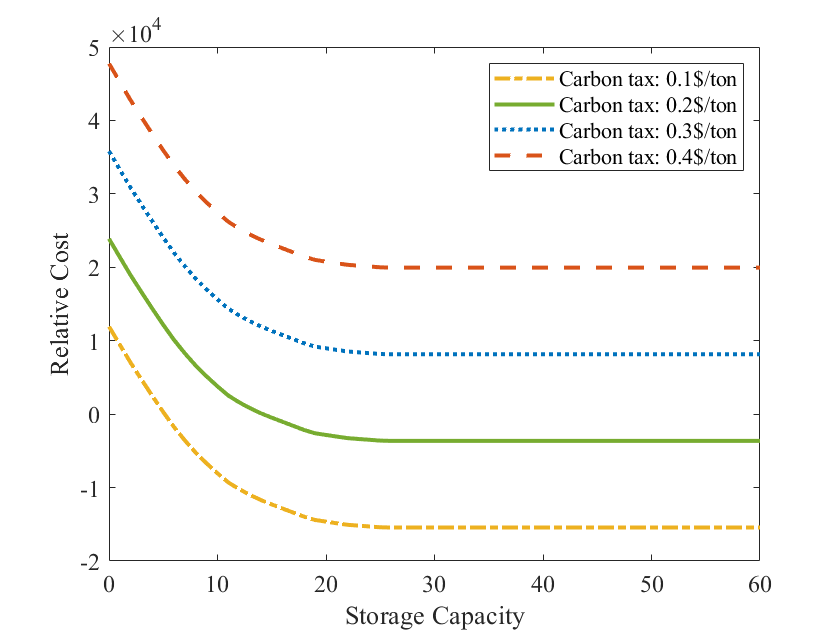

figure
fval_base=fval_show(1,1);
% plot (storage_size_range,fval_show(1,:),'--','color',[0.8500 0.3250 0.0980],'lineWidth',2)
% hold on
plot(storage_size_range,fval_show(2,:)-fval_base,'-.','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(storage_size_range,fval_show(3,:)-fval_base,'-','color',[0.4660 0.6740 0.1880],'lineWidth',2)
hold on
plot(storage_size_range,fval_show(4,:)-fval_base,':','color',[0 0.4470 0.7410],'lineWidth',2)
hold on
plot(storage_size_range,fval_show(5,:)-fval_base,'--','color',[0.8500 0.3250 0.0980],'lineWidth',2)

legend('Carbon tax: 0.1$/ton', 'Carbon tax: 0.2$/ton','Carbon tax: 0.3$/ton','Carbon tax: 0.4$/ton')
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Relative Cost','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Storage Capacity','FontSize',13.2,'FontName','Times New Ron','FontWeight','Bold')

## Considering Capital Cost

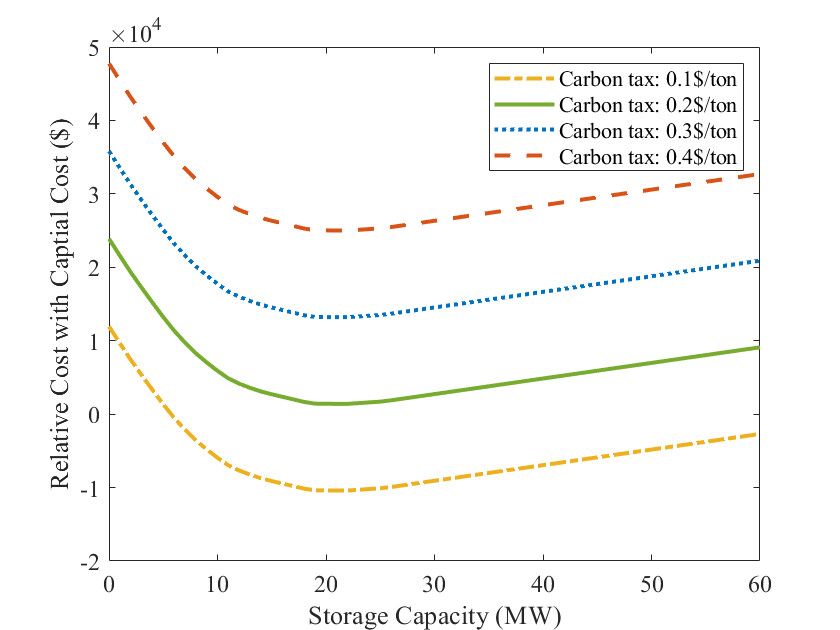

figure
fval_show_cut=fval_show-fval_base;
for i=1:tax_size
    for j=1:size_size
        bb_size=storage_size_range(1,j);
        fval_show_cut(i,j)=fval_show_cut(i,j)+bb_size*N*1.8;
    end
end
plot(storage_size_range,fval_show_cut(2,:),'-.','color',[0.9290 0.6940 0.1250],'lineWidth',2)
hold on
plot(storage_size_range,fval_show_cut(3,:),'-','color',[0.4660 0.6740 0.1880],'lineWidth',2)
hold on
plot(storage_size_range,fval_show_cut(4,:),':','color',[0 0.4470 0.7410],'lineWidth',2)
hold on
plot(storage_size_range,fval_show_cut(5,:),'--','color',[0.8500 0.3250 0.0980],'lineWidth',2)

legend('Carbon tax: 0.1$/ton', 'Carbon tax: 0.2$/ton','Carbon tax: 0.3$/ton','Carbon tax: 0.4$/ton')
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Relative Cost with Captial Cost ($)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Storage Capacity (MW)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')

carbon_tax_ton_range=0:1:3;
ton_lb_transit=2204*10^1;
carbon_tax_range=carbon_tax_ton_range./ton_lb_transit;
tax_size=size(carbon_tax_range,2);
storage_size_range=0:10:30;
size_size=size(storage_size_range,2);
fval_show=zeros(tax_size,size_size);
fval_show_e=zeros(tax_size,size_size);
fval_show_g=zeros(tax_size,size_size);
fval_show_all=zeros(tax_size,size_size,3);
fval_show_all_e=zeros(tax_size,size_size,3);
fval_show_all_g=zeros(tax_size,size_size,3);
epsilon=0.1; % can be changed
gamma=0.5; % can be changed

for i=1:tax_size
    carbon_tax=carbon_tax_range(1,i);
    [p,q,p_e,q_e,p_g,q_g]=gen_unit_price_respectively(g_type,carbon_tax);
    for j=1:size_size
        bb_size=storage_size_range(1,j);
        bb=ones(N,1)*bb_size;
%         bb=zeros(N,1);
%         for k=1:w_num
%             loc=w_loc(k);
%             bb(loc,1)=bb_size; 
%         end
        ramp_rate=0.5; 
        umin_ori=-ramp_rate*bb;                                                                                                                 
        umax_ori=ramp_rate*bb;
        [x,fval_show(i,j)]=MinC(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,umin_ori,umax_ori,DR,UR);
        G=reshape(x(1:T*N),N,T);
        [fval_show_e(i,j),fval_show_g(i,j)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G);
        [xx,fval_show_all(i,j,:)]=gen_performance_for_3_formulations(T,N,M,bb,d_f,p,q,H,fmax,g_min,g_max,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);
        G_1=reshape(xx(1:T*N,1),N,T);
        [fval_show_all_e(i,j,1),fval_show_all_g(i,j,1)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G_1);
        G_3=reshape(xx(1:T*N,3),N,T);
        [fval_show_all_e(i,j,1),fval_show_all_g(i,j,3)]=gen_cost_respectively(p_e,q_e,p_g,q_g,G_3);
    end
end


**line congestion:**

% fmax_con=fmax;
% fmax_con(38,1)=100;
% % fmax_con(93,1)=100;
% % fmax_con(7,1)=100;
% fmax_con(155,1)=100;
% fval_show_con=zeros(tax_size,size_size);
% fval_show_all_con=zeros(tax_size,size_size,3);
% for i=1:tax_size
%     carbon_tax=carbon_tax_range(1,i);
%     [p,q]=gen_unit_price(g_type,carbon_tax);                                                                                        
%     for j=1:size_size
%         bb_size=storage_size_range(1,j);
%         bb=ones(N,1)*bb_size;       
% %         bb=zeros(N,1);
% %         for k=1:w_num
% %             loc=w_loc(k);
% %             bb(loc,1)=bb_size; 
% %         end
%         ramp_rate=0.5; 
%         umin_ori=-ramp_rate*bb;
%         umax_ori=ramp_rate*bb;
%         [~,fval_show_con(i,j)]=MinC(T,N,M,bb,d_f,p,q,H,fmax_con,g_min,g_max,umin_ori,umax_ori);
%         [~,fval_show_all_con(i,j,:)]=gen_performance_for_3_formulations(T,N,M,bb,d_f,p,q,H,fmax_con,g_min,g_max,ramp_rate,epsilon,gamma,error_data,w_loc,w_num);
%     end
% end

subplot(1,3,1)
plot (storage_size_range,fval_show(1,:),'-','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show(2,:),'-','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show(3,:),'-','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show(4,:),'-','color',[0 0.4470 0.7410])
%legend('Carbon tax: 0', 'Carbon tax: 0.1','Carbon tax: 0.2','Carbon tax: 0.3')
hold on
plot (storage_size_range,fval_show_all(1,:,1),'--','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all(2,:,1),'--','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all(3,:,1),'--','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all(4,:,1),'--','color',[0 0.4470 0.7410])
hold on
plot (storage_size_range,fval_show_all(1,:,3),':','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all(2,:,3),':','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all(3,:,3),':','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all(4,:,3),':','color',[0 0.4470 0.7410])
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Performance','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
xlabel('Storage Capacity','FontSize',13.2,'FontName','Times New Ron','FontWeight','Bold')
subplot(1,3,2)
plot (storage_size_range,fval_show_e(1,:),'-','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_e(2,:),'-','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_e(3,:),'-','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_e(4,:),'-','color',[0 0.4470 0.7410])
%legend('Carbon tax: 0', 'Carbon tax: 0.1','Carbon tax: 0.2','Carbon tax: 0.3')
hold on
plot (storage_size_range,fval_show_all_e(1,:,1),'--','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all_e(2,:,1),'--','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all_e(3,:,1),'--','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all_e(4,:,1),'--','color',[0 0.4470 0.7410])
hold on
plot (storage_size_range,fval_show_all_e(1,:,3),':','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all_e(2,:,3),':','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all_e(3,:,3),':','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all_e(4,:,3),':','color',[0 0.4470 0.7410])
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Performance','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold' )
xlabel('Storage Capacity','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
subplot(1,3,3)
plot (storage_size_range,fval_show_g(1,:),'-','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_g(2,:),'-','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_g(3,:),'-','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_g(4,:),'-','color',[0 0.4470 0.7410])
%legend('Carbon tax: 0', 'Carbon tax: 0.1','Carbon tax: 0.2','Carbon tax: 0.3')
hold on
plot (storage_size_range,fval_show_all_g(1,:,1),'--','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all_g(2,:,1),'--','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all_g(3,:,1),'--','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all_g(4,:,1),'--','color',[0 0.4470 0.7410])
hold on
plot (storage_size_range,fval_show_all_g(1,:,3),':','color',[0.8500 0.3250 0.0980])
hold on
plot(storage_size_range,fval_show_all_g(2,:,3),':','color',[0.9290 0.6940 0.1250])
hold on
plot(storage_size_range,fval_show_all_g(3,:,3),':','color',[0.4660 0.6740 0.1880])
hold on
plot(storage_size_range,fval_show_all_g(4,:,3),':','color',[0 0.4470 0.7410])
set(gca,'FontSize',12,'FontName','Times New Roman')
ylabel('Performance','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold' )
xlabel('Storage Capacity','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')